**PART TWO**

Loading Image features save and Comparing with features saved from Initial Image

**step 1:** Connect to Webcam

cam = webcam();

**Step 2:** Capture Saved Image and Extract Features

newImage = snapshot(cam);

**Step 3**: Convert to Grayscale and Detect Face in Image

newImageGray = rgb2gray(newImage);
faceDetector = vision.CascadeObjectDetector();
bboxes = step(faceDetector, newImageGray);

**Step 4:** Comparing the new features with the ones we’ve already got stored and setting an Accuracy Threshold.

if ~isempty(bboxes)
    [~, largestFaceIdx] = max(bboxes(:,3) .* bboxes(:,4)); 
    newFaceBox = bboxes(largestFaceIdx, :);
    newFaceImg = imcrop(newImageGray, newFaceBox);
    newFaceImgResized = imresize(newFaceImg, [128 128]);
    newHOGFeatures = extractHOGFeatures(newFaceImgResized);
    load('mainFaceHOGFeatures.mat', 'mainHOGFeatures');
    distance = norm(newHOGFeatures - mainHOGFeatures);
    threshold = 6.5; 
    if distance < threshold
        disp('Access Granted');
    else
        disp('Access Denied');
    end

**Step 5: ** Displaying the new face image we just captured

Access Denied


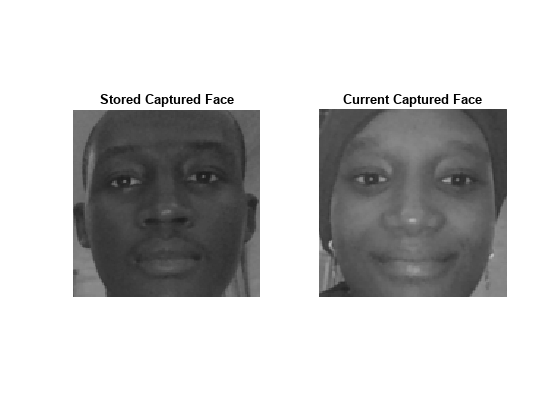

    figure;
    subplot(1, 2, 1); 
    imshow(mainFaceImgResized);
    title('Stored Captured Face');
    subplot(1, 2, 2); 
    imshow(newFaceImgResized);
    title('Current Captured Face');
else
    disp('No face detected. Please try again.');
end

**Final Step:**  clear the webcam

clear cam;